# The Gesture-Field-Register (GFR) model of F0 control

## Installation

Download the model from [https://github.com/tilsen/F0_model.git](https://github.com/tilsen/F0_model.git) or clone the repository to a local directory.

To use the model, run the following command:

cd(fileparts(matlab.desktop.editor.getActiveFilename)); %switch to directory containing this file
addpath(genpath(".")) ;

clear all; %for running this livescript

## Model overview

The Gesture-Field-Register (GFR) model is described in Kim, S.E. & Tilsen, S. (xxxx). The Gesture-Field-Register (GFR) model of F0 Control. xxxx. The model generates F0 contours using three mechanisms:

- F0 gestures: gestural systems that, when active, influence the control of F0.

- F0 planning field: a dynamic field representation of a normalized F0 target state.

- Register control: a dynamic mapping from the normalized F0 control system to physical units (Hz)

## Synthesizing F0 contours

In many circumstances one will want to fit model parameters to data, but it is also possible to specify parameters and synthesize an F0 contour. The following need to be specified to generate an F0 contour: 

- a specification of F0 gestures

- a time range

- initial F0 and F0 velocity

- a set of model parameters

- (optional) prosodic phrase unit times

The steps for generating an F0 contour are shown below.

Define gestures:

gests = {{'H' 'L'}}; % a sequence of a H and L F0 gesture

Create a structure (`data`) containing the information needed for contour synthesis. This is minimially the time steps at which to generate the contour (should be equally spaced) and an initial F0. It may optionally include the times of prosodic units (such as prosodic words -- an example of this is shown below). In the case of optimization (example further below), `data` will also contain an empirical trajectory that is used to initialize parameters and set bounds.

% time steps:
data.t = {0:0.001:0.5};

% specifying two values here will also determine an initial velocity,
% otherwise the initial velocity is assumed to be 0:
data.y = {[130]};

The function `gen_structure` constructs several variables that contain information about the model and initializes a structure for the model itself.

M0 = gen_structure(gests,data); 

No prosodic units specified, assuming one unit
.

The structure `M` contains information about the model:

disp(M0);

            t: [501×1 double]
       pw_ixs: [501×1 logical]
           dt: 1.0000e-03
           Nf: 100
           f0: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0]
            f: [0 0.0101 0.0202 0.0303 0.0404 0.0505 0.0606 0.0707 0.0808 0.0909 0.1010 0.1111 0.1212 0.1313 0.1414 0.1515 0.1616 0.1717 0.1818 0.1919 0.2020 0.2121 0.2222 0.2323 0.2424 0.2525 0.2626 0.2727 0.2828 0.2929 0.3030 0.3131 0.3232 0.3333 … ]
           Nt: 501
        pw_t0: 0
        pw_t1: 0.5000
            A: [2×6 table]
            G: [2×5 table]
           x0: 130
           v0: 0
    model_fcn: @(b,m)f0mod(b,m)
     cost_fcn: @(b,m)f0mod_cost(b,m,D.y{1})
            P: [1×3 table]



A table for each gestural system:

disp(M0.G);

    name      pw      order    id          color      
    _____    _____    _____    __    _________________

    {'H'}    {[1]}    {[1]}    1     0.8    0.8    0.8
    {'L'}    {[1]}    {[2]}    2     0.5    0.5    0.5



A table for each gestural activation event. Since the same gestural system may have multiple activation events, the mapping from G to A is in general one-to-many:

disp(M0.A);

    name     pw    order    id    gestid          color      
    _____    __    _____    __    ______    _________________

    {'H'}    1       1      1       1       0.8    0.8    0.8
    {'L'}    1       2      2       2       0.5    0.5    0.5



A table for each prosodic unit. If prosodic unit times are not specified in the `data` structure, `gen_structure` assumes that there is only one unit.

disp(M0.P);

    id    t0    t1 
    __    __    ___

    1     0     0.5



Generate and initialize parameters:

PAR = gen_params(M0,data); % generate a parameter structure
disp(PAR)

         name          fixed    value     lb      b0     ub                                            descr                                                 replicates     
    _______________    _____    _____    ____    ____    ___    ____________________________________________________________________________________    ____________________

    {'targ_01'    }    false     NaN        0     0.5      1    {'target for gesture (normalized units); mean/mode of the field distribution: 01'  }    {'gestures'        }
    {'targ_02'    }    false     NaN        0     0.5      1    {'target for gesture (normalized units); mean/mode of the field distribution: 02'  }    {'gestures'        }
    {'sigma_01'   }    true      Na

(Optional) adjust parameters

% e.g. set H target to 1, L onset to 0.200 s, and L duration to 0.150 s.
% Numbers at the end of the parameter names (e.g., 01 of targ_01) correspond to
% gestures/activation events/units (see "replicates" column).
% For all other non-specified parameters, initial values (b0) are used.
PAR = set_parameter(PAR,'targ_01',1); 
PAR = set_parameter(PAR,'ons_02',0.200);
PAR = set_parameter(PAR,'dur_02',0.150);

Assign the parameters to the model:

M0 = assign_params(M0,PAR);

Generate the F0 contour:

[y,M0] = f0mod(M0.BETA.value,M0); % first output is the f0 contour, second output is the model structure with model-internal variables

Plot the F0 contour

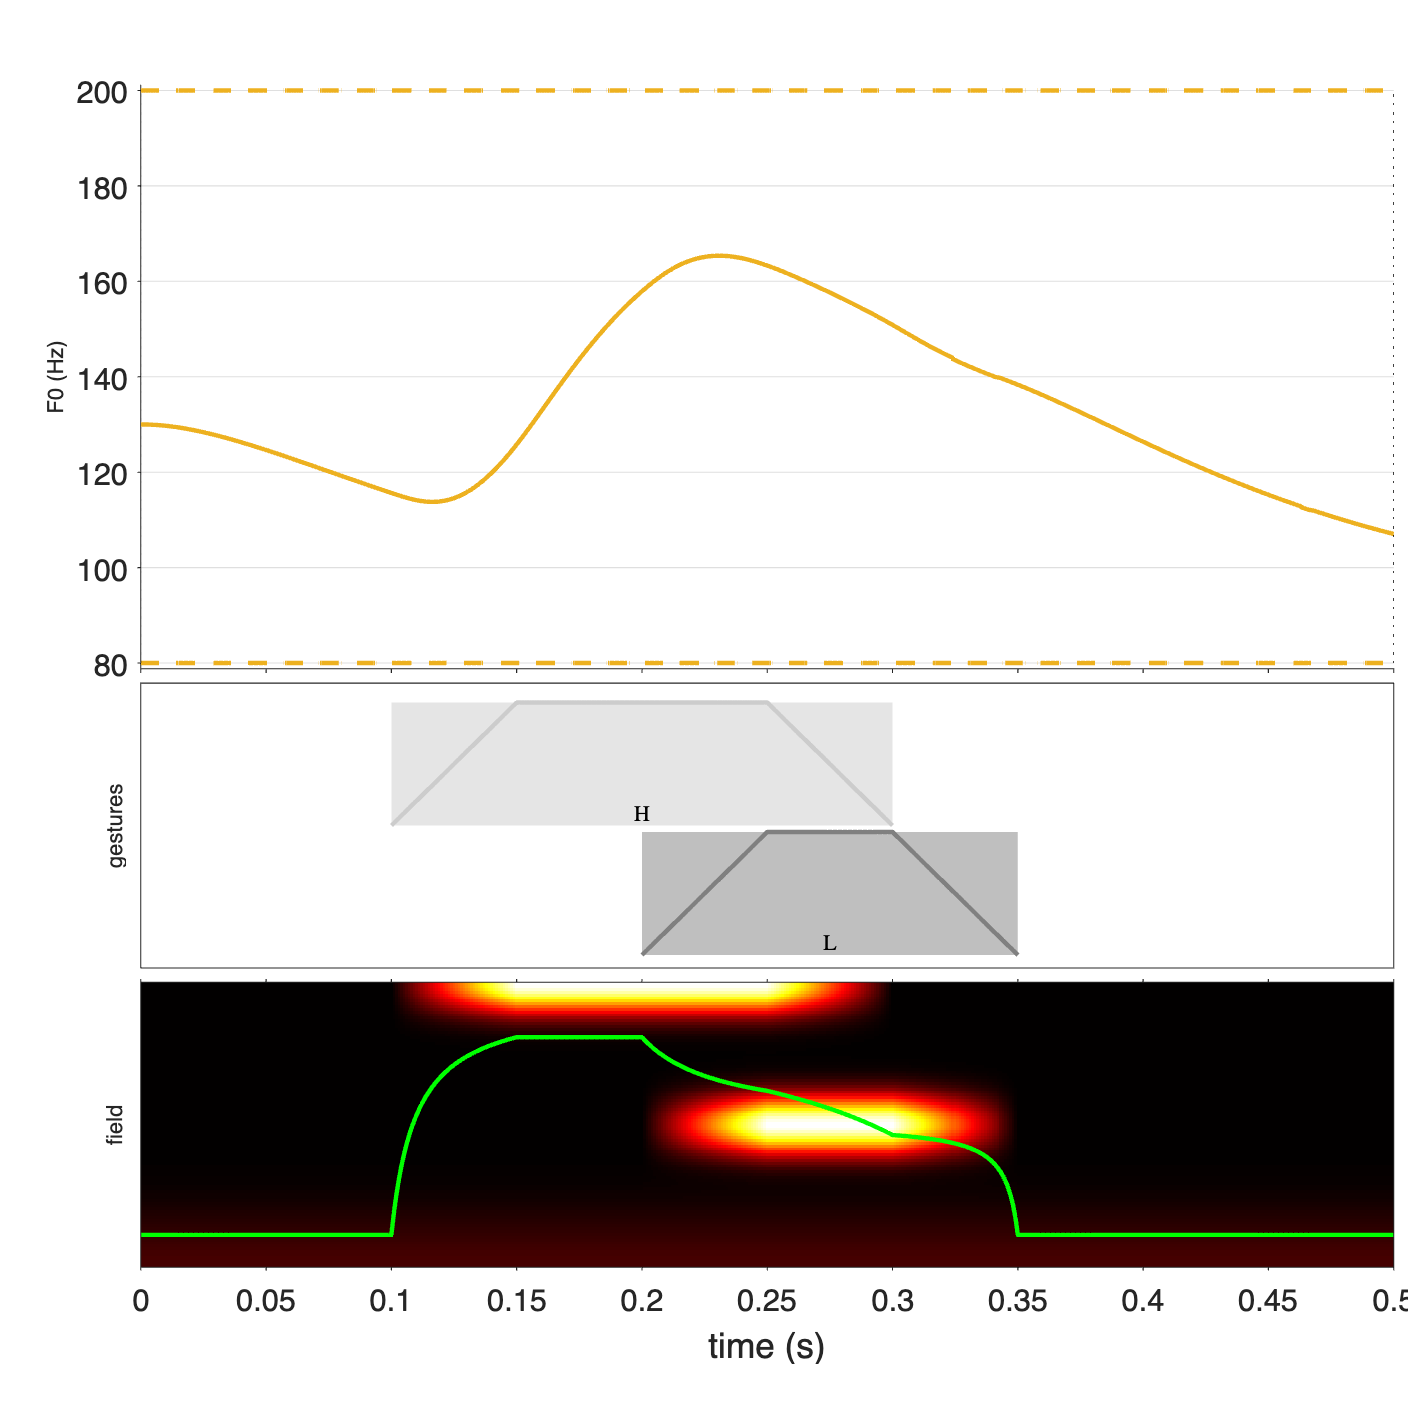

figls; plot_model(M0,[],gcf);

### Specifying prosodic units

A flat structure of prosodic units (such as prosodic words) can be specified. In order to do this, put the gestures associated with each unit in separate elements of the array:

gests = {{'H' 'L'},{'H'}}; % two prosodic units: one with a sequence of a H and L F0 gesture, and the other with a single H gesture

You also need to specify the onset and offset times of the prosodic words.

data.t = {0:0.001:1};
data.pw_t0 = {[0 0.5]};
data.pw_t1 = {[0.5 1]};

Generate the model structure and parameters

M1 = gen_structure(gests,data); % generates gestures and gestural activation events tables
PAR = gen_params(M1,data);

Note that gestural onset times are specified relative to the onset of the prosodic unit that they are associated with:

PAR = set_parameter(PAR,'ons_02',0.2); % the gesture starts 0.2s after the onset of the prosodic unit
PAR = set_parameter(PAR,'ons_03',0.1); % the gesture starts 0.1s after the onset of the prosodic unit
disp(PAR);

         name          fixed    value     lb      b0     ub                                            descr                                                 replicates     
    _______________    _____    _____    ____    ____    ___    ____________________________________________________________________________________    ____________________

    {'targ_01'    }    false     NaN        0     0.5      1    {'target for gesture (normalized units); mean/mode of the field distribution: 01'  }    {'gestures'        }
    {'targ_02'    }    false     NaN        0     0.5      1    {'target for gesture (normalized units); mean/mode of the field distribution: 02'  }    {'gestures'        }
    {'sigma_01'   }    true      Na

A register event can be specified at a prosodic unit boundary as follows:

M1.register = 'byunit';

% register is compressed in the second phrasal unit:
PAR = set_parameter(PAR,'span_02',80);

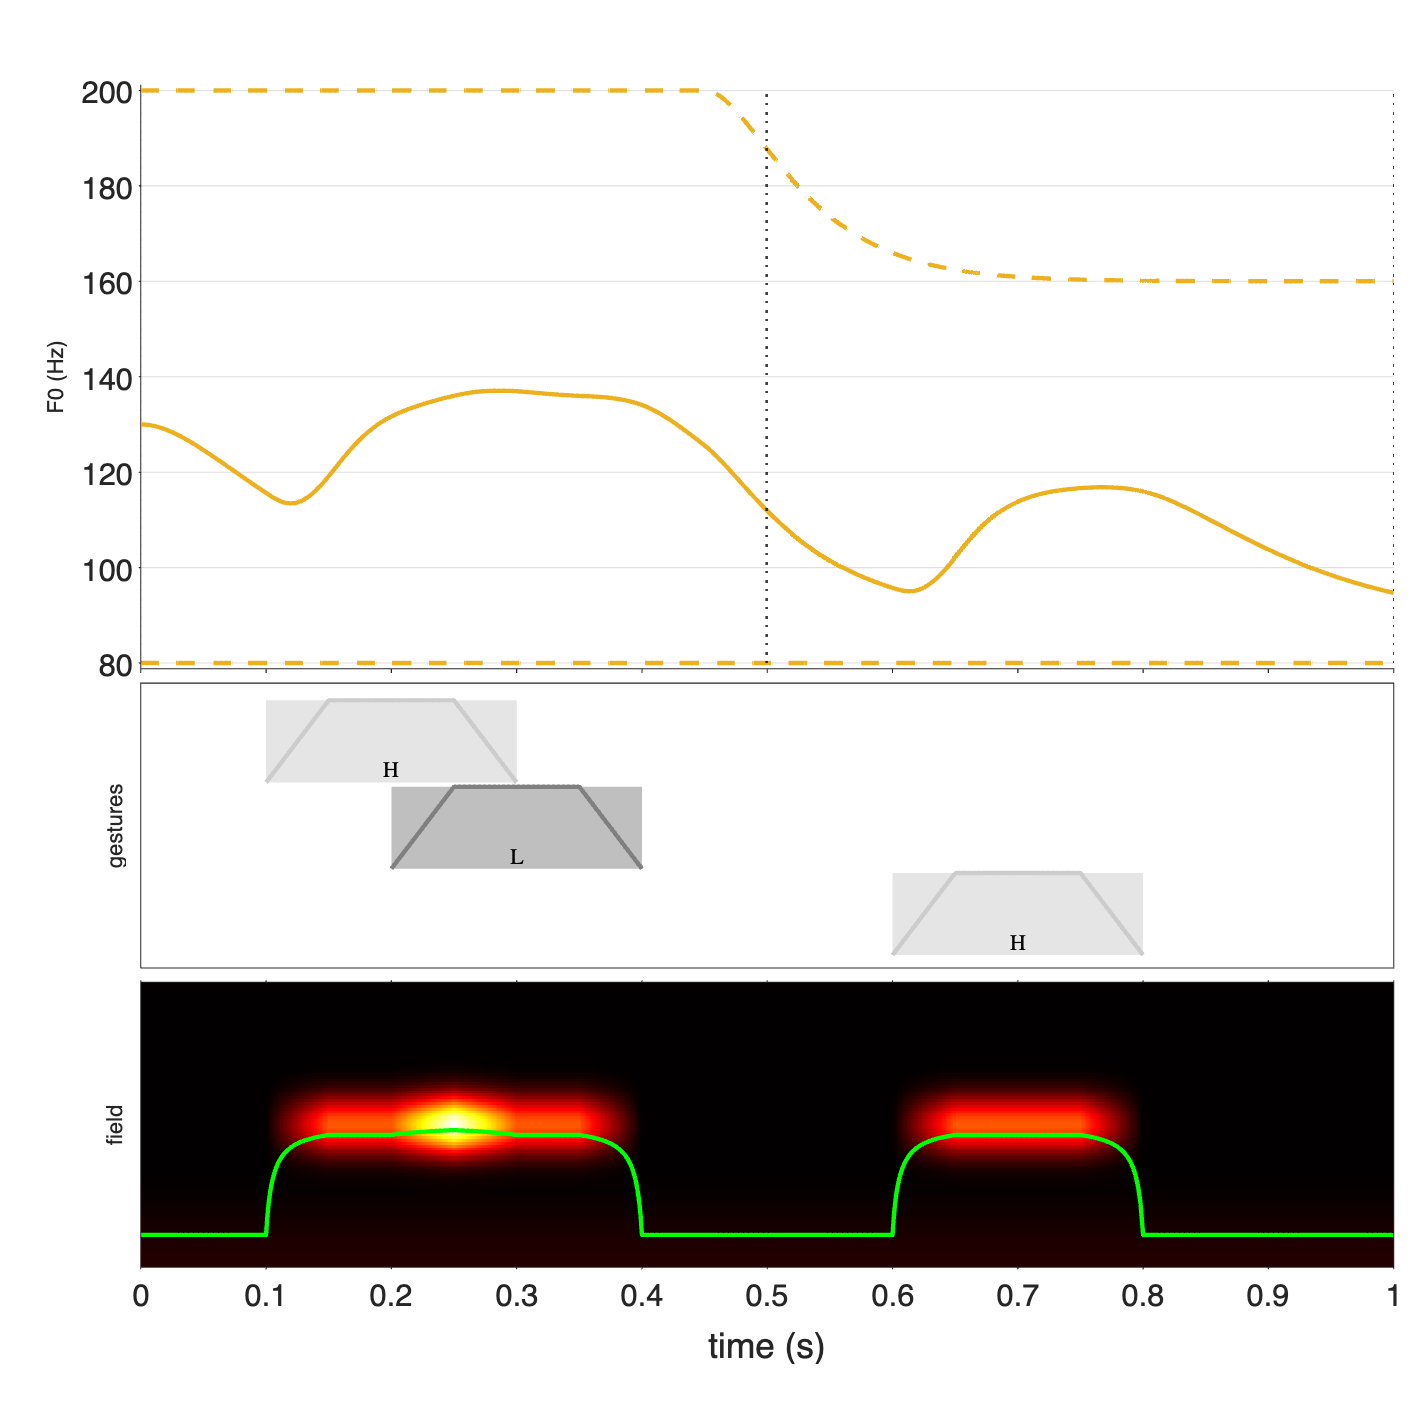

M1 = assign_params(M1,PAR);
[~,M1] = f0mod(M1.BETA.value,M1); %adds extra outputs
figls; plot_model(M1,[],gcf);

## Fitting empirical data

Often it is useful to fit the model to empirical data. In this case, the f0 trajectory of the empirical data is needed:

load(['.' filesep 'data' filesep 'data_optimization_example.mat'],'data');
disp(data);

         subj: 'PA01'
    condition: '2S'
            t: {[0 0.0050 0.0100 0.0150 0.0200 0.0250 0.0300 0.0350 0.0400 0.0450 0.0500 0.0550 0.0600 0.0650 0.0700 0.0750 0.0800 0.0850 0.0900 0.0950 0.1000 0.1050 0.1100 0.1150 0.1200 0.1250 0.1300 0.1350 0.1400 0.1450 0.1500 0.1550 0.1600 0.1650 … ]}
            y: {[95.9258 95.9116 95.9008 95.8930 95.8876 95.8839 95.8815 95.8802 95.8796 95.8800 95.8814 95.8839 95.8883 95.8953 95.9057 95.9203 95.9397 95.9645 95.9951 96.0318 96.0753 96.1260 96.1848 96.2527 96.3307 96.4200 96.5221 96.6382 96.7696 … ]}
         y_pw: {1×3 cell}
        pw_t0: {[0 1.0350]}
        pw_t1: {[1.0350 2.2200]}
       pw_dur: [1.0350 1.1850]
          Npw: 2



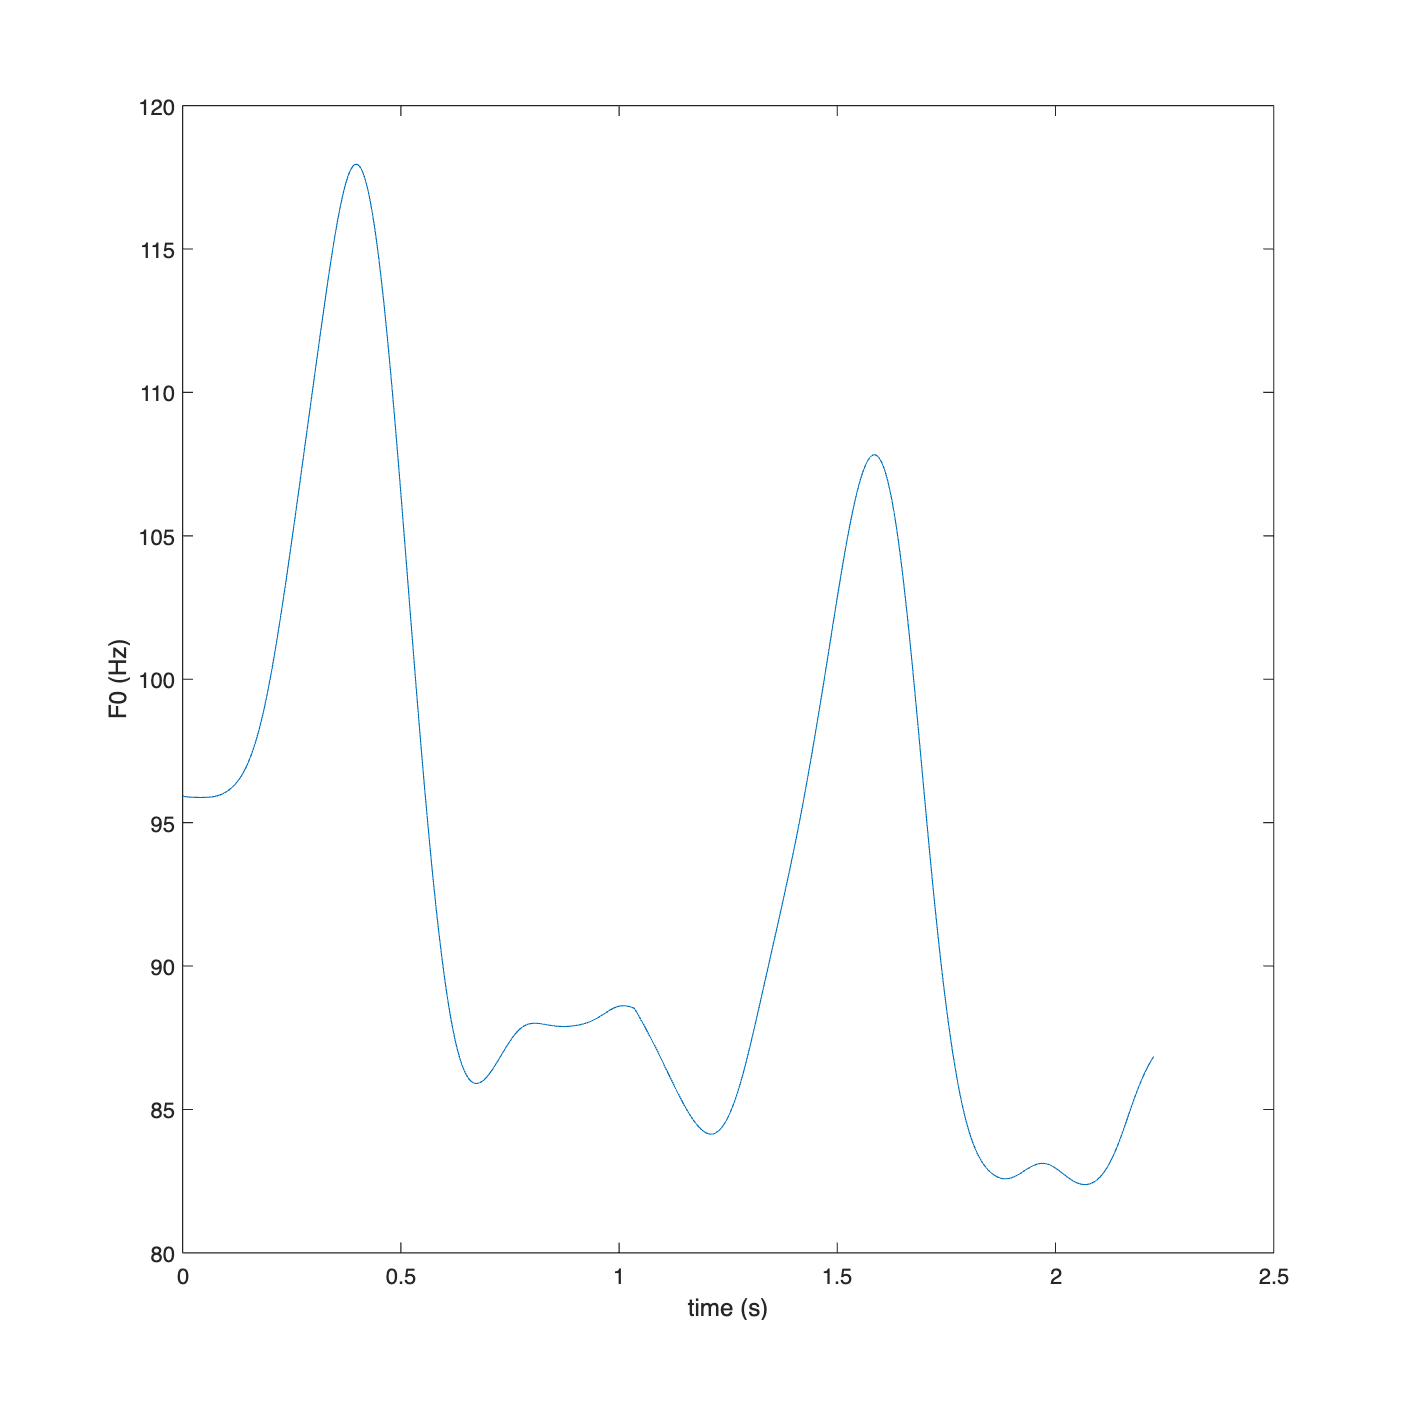

figls; plot(data.t{1},data.y{1}); ylabel('F0 (Hz)'); xlabel('time (s)');

Define gestures. In this example, we have two prosodic units, each of which we hypothesize to be composed of a sequence of H and L gestures, hence:

gests = {{'H' 'L'},{'H' 'L'}};
M2 = gen_structure(gests,data); % generates gestures and gestural activation events tables

Initialize parameters. As long as the provided f0 contour is the same length as the time steps, the function `init_params `inside `gen_params `will initialize parameter values on the basis of the provided contour:

PAR = gen_params(M2,data); %generate a parameters structure

Notice that parameters bounds are imposed on the basis of the empirical data provided:

disp(PAR);

         name          fixed    value      lb         b0        ub                                             descr                                                 replicates     
    _______________    _____    _____    _______    ______    ______    ____________________________________________________________________________________    ____________________

    {'targ_01'    }    false     NaN           0         1         1    {'target for gesture (normalized units); mean/mode of the field distribution: 01'  }    {'gestures'        }
    {'targ_02'    }    false     NaN           0         0         1    {'target for gesture (normalized units); mean/mode of the field distribution: 02'  }    {'gestures'        }
   

(Optional) adjust parameter bounds:

%impose different target bounds for H vs. L gestures:
hids = arrayfun(@(c){sprintf('%02d',c)},M2.G.id(contains(M2.G.name,'H')));
lids = arrayfun(@(c){sprintf('%02d',c)},M2.G.id(contains(M2.G.name,'L')));
hix = ismember(PAR.name,append('targ_',hids));
lix = contains(PAR.name,append('targ_',lids));
PAR.lb(hix) = 0.5;  %the lower bound of the H gesture
PAR.ub(lix) = 0.5;  %the upper bound of the L gesture

Assign parameters to the model:

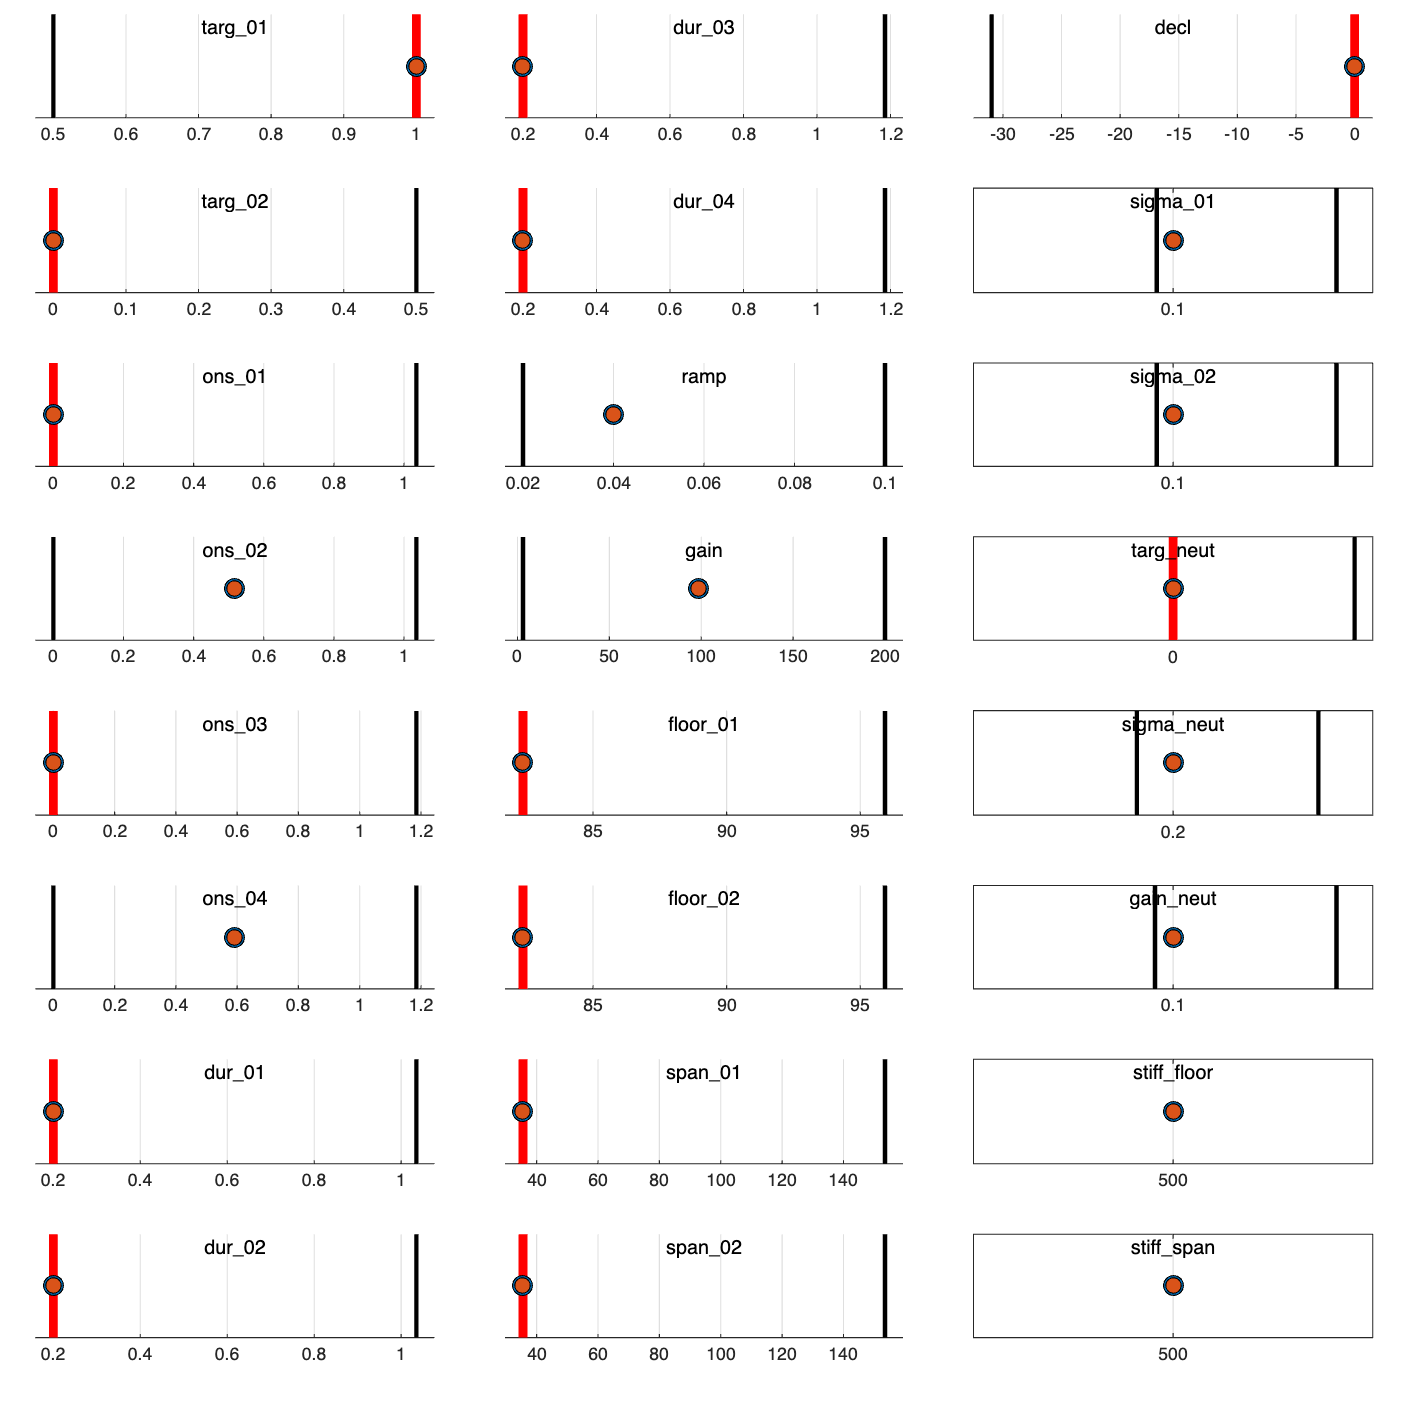

M2 = assign_params(M2,PAR);
figls; plot_params(M2,gcf);

Impose constraints. To improve the optimization results, inequality constraints can be imposed. For the optimization of gestural timing parameters (onsets and durations), it is particularly useful to impose constraints that ensure correct ordering of gestural activation events. For example:

%gestures in the same pwrd cannot overlap more than this value:
M2 = ineq_constraints(M2,'gest_overlap',0.100); 

%gestures cannot extend beyond the end of the prosodic unit by more than this value
M2 = ineq_constraints(M2,'gest_endpw',0.0);

View the initial fit:

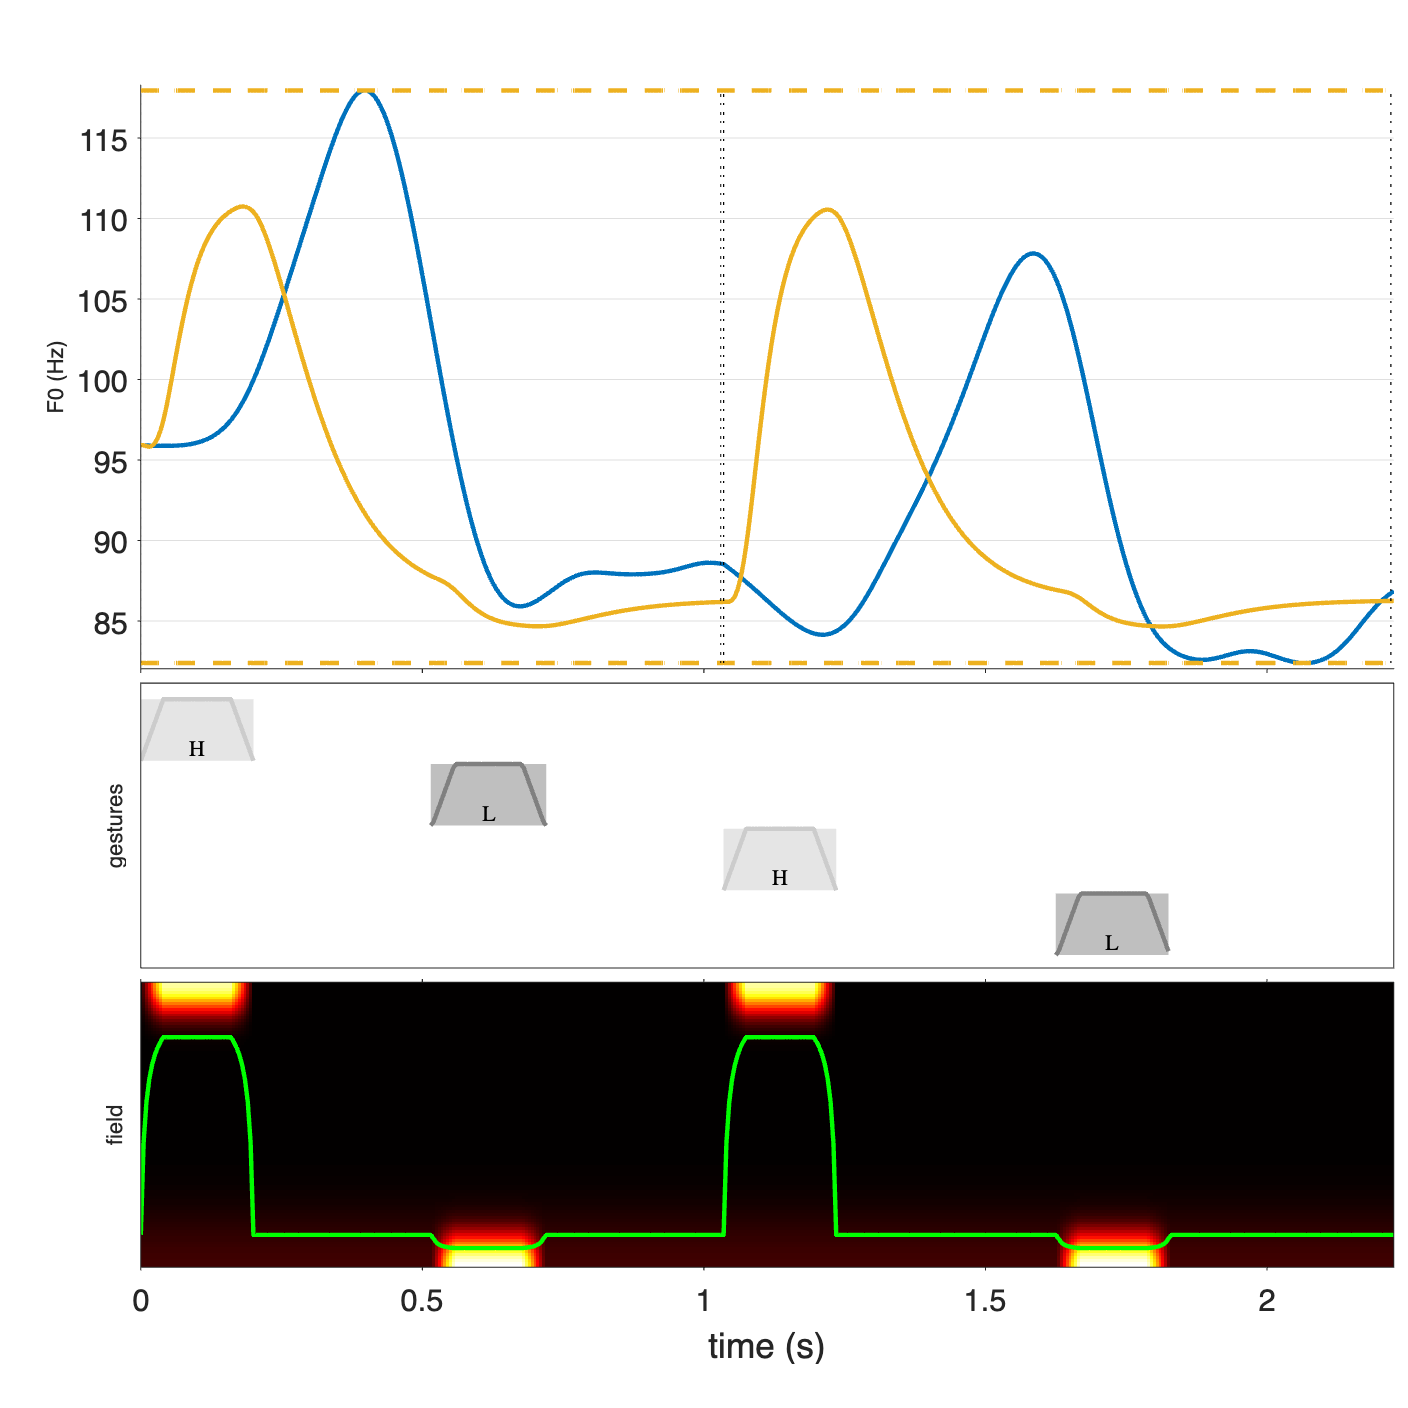

figls; plot_model(M2,data.y{1},gcf); % blue: empirical contour, yellow: initial fit

The cost of the initial fit can be assesed by generating an f0 contour with the initial parameters:

fprintf('cost of initial fit (MSE): %1.1f\n',M2.cost_fcn(M2.BETA.b0,M2));

cost of initial fit (MSE): 145.3


Conduct the optimization:

options = optimoptions('patternsearch','Display','none','InitialMeshSize',0.1,'UseParallel',true,'MaxIterations',100);

cost_fcn = @(b)M2.cost_fcn(b,M2);

%uncomment to run the optimization (will take a while):
%[betahat,val] = patternsearch(cost_fcn,M.BETA.b0,M.CON.A,M.CON.b,[],[],M.BETA.lb,M.BETA.ub,options);

%load the optimized parameters instead of running the optimization 
%(see ./examples/optimization_example.m)
load("./data/params_optimization_example.mat",'betahat');

fprintf('cost of optimized model fit (MSE): %1.1f\n',M2.cost_fcn(betahat,M2));

cost of optimized model fit (MSE): 2.6


Plot the synthesized F0 contour from the optimized model along with the empirical F0 contour:

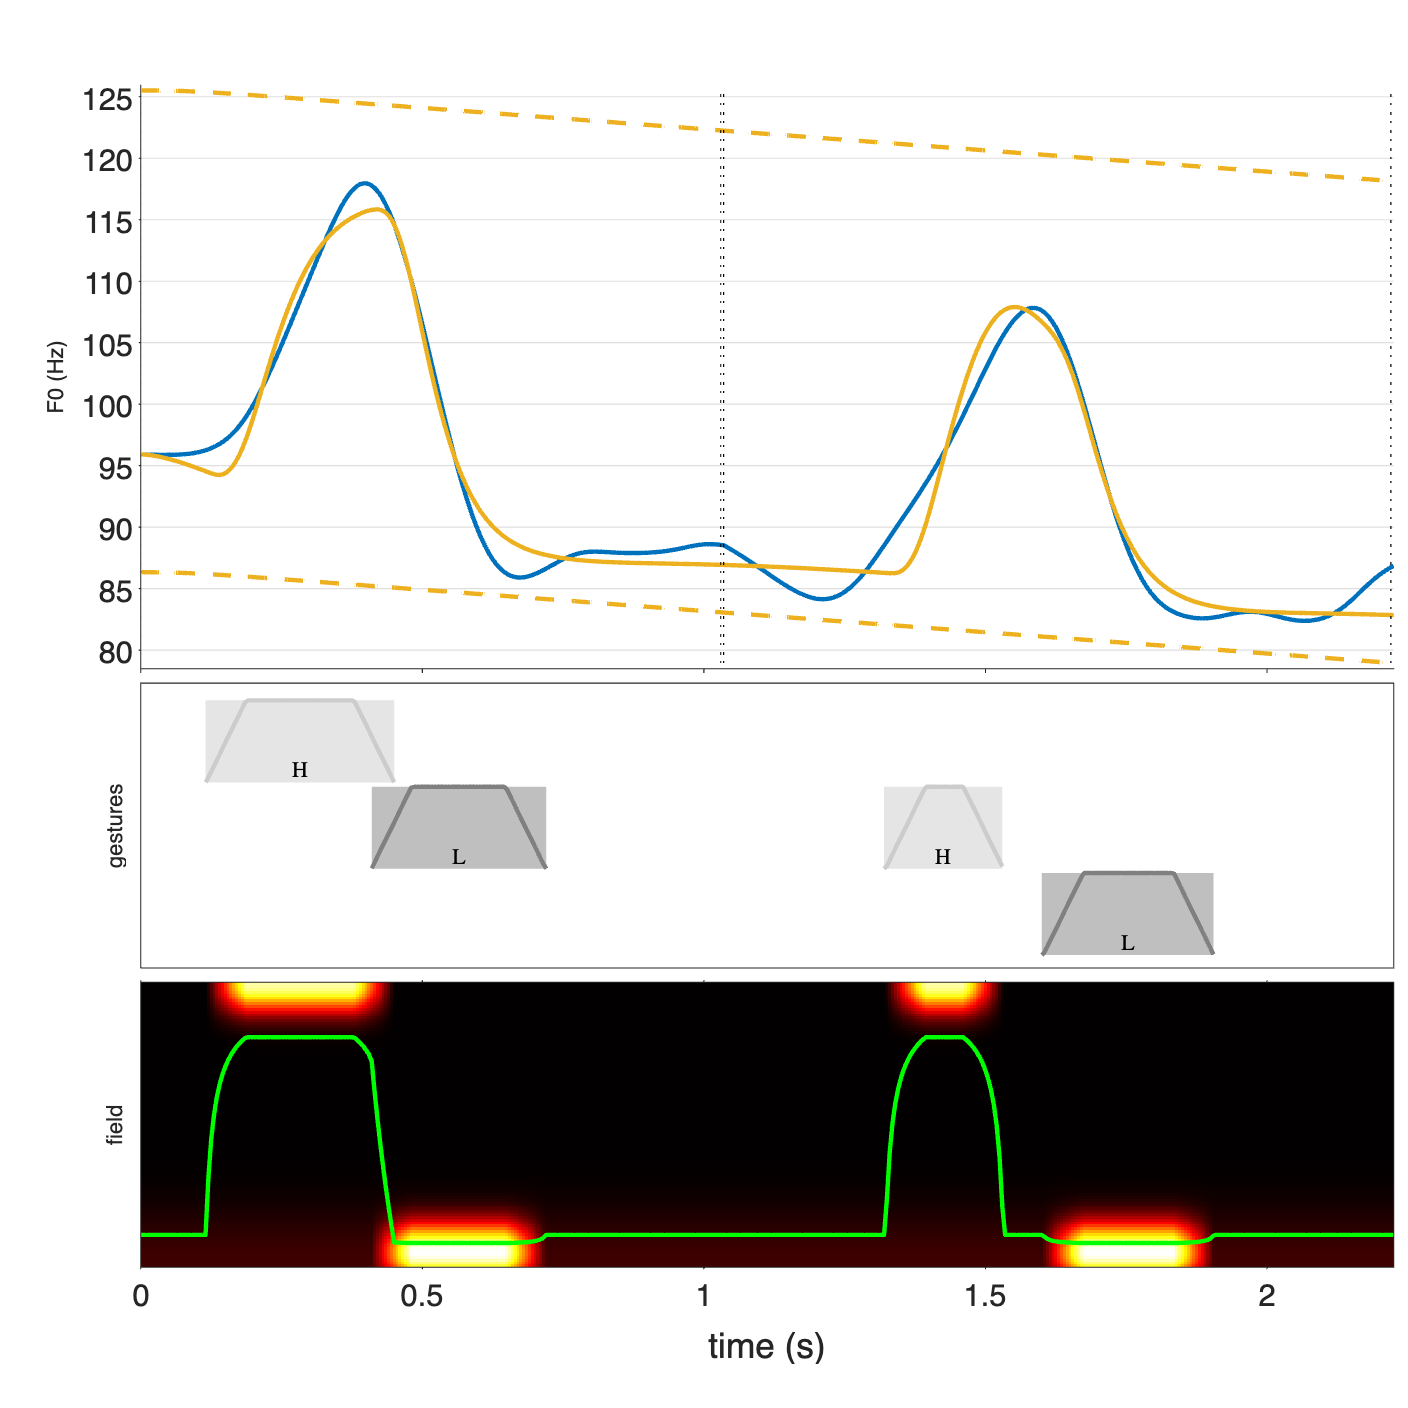

M2.BETA.value = betahat; %add optimized parameters to table
figls; plot_model(M2,data.y{1},gcf); % blue: empirical contour, yellow: optimized fit

Inspect the optimized parameter values:

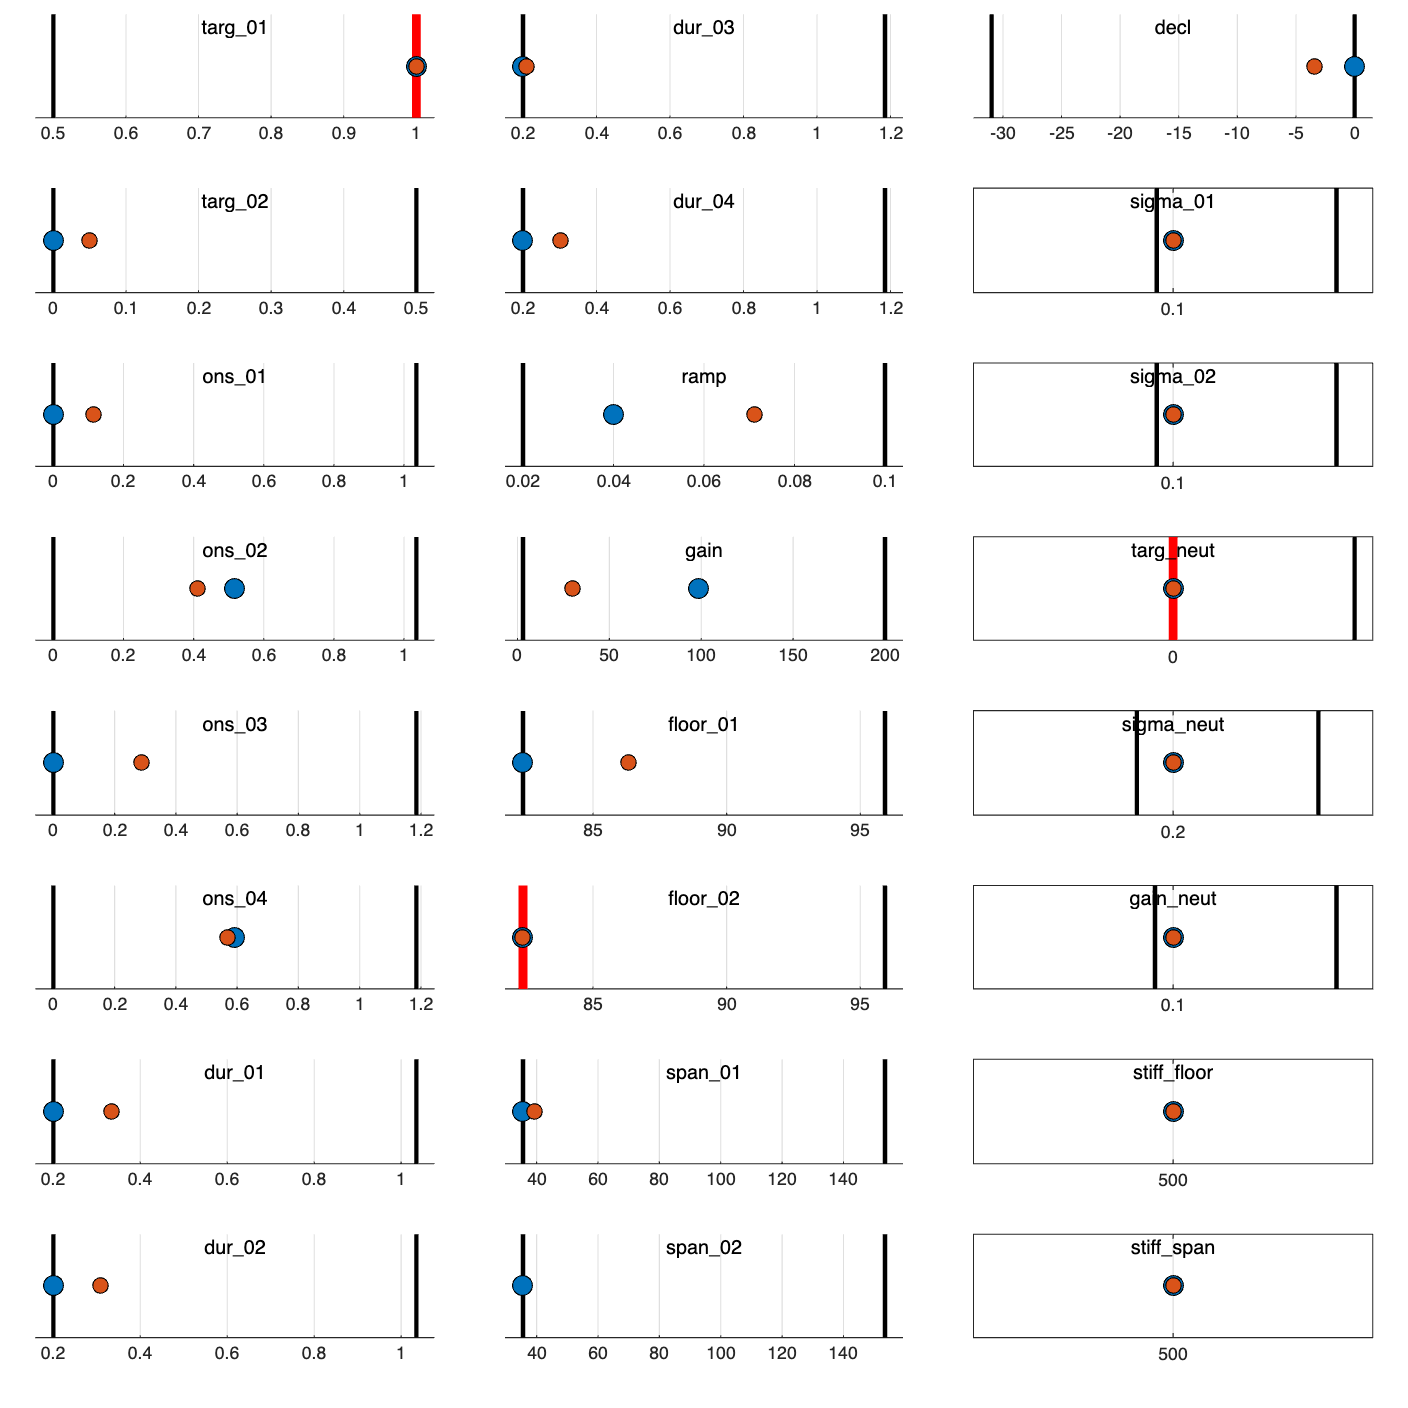

figls; plot_params(M2,gcf); % blue: initial param values, orange: optimized values

### Optimization hyperparameters

In experimenting with different global optimization methods that allow for bounds and inequality constraints (particle swarm, simulated annealing, and pattern search), we found the pattern search algorithm to be the most effective. The parameters `InitialMeshSize` and `MaxIterations` can be decreased/increased to improve the likelihood that the algorithm finds a true global minimum. However, these adjustments will also increase the time it takes for the optimization to run.

One downside of the pattern search algorithm is that it is deterministic: given the same starting parameter values, it will always identify the same point in parameter space. Hence in order to have more certainty that the algorithm is identifying a global minimum, we found it necessary to conduct the optimization multiple times, each time perturbing the starting parameter values by jittering them. This can be accomplished with the functions `random_params` or `random_perturb_params:`

% random parameters within the specified bounds:
M2a.BETA.b0 = random_params(M2.BETA);

% randomly raise or lower parameter values by a value that is within a
% proportion of the range of their bounds. The proportion is
% perturb_magnitude:
perturb_magnitude = 0.1;
M2b.BETA.b0 = random_perturb_params(M2.BETA,M2.BETA.b0,perturb_magnitude);

function [] = figls()
figure('position',[0 0 640 640]); %appropriate size for livescript
end